close all; clc; clearvars;

T = readtable("CaracteristicasDETECCIONGLAUCOMA.csv");
T_error = readtable("T_buenacalidad_revisadas_ERRORES3.csv");
T_metadata = readtable("metadataCALIDADCORRECTA.csv");

#### Correlation

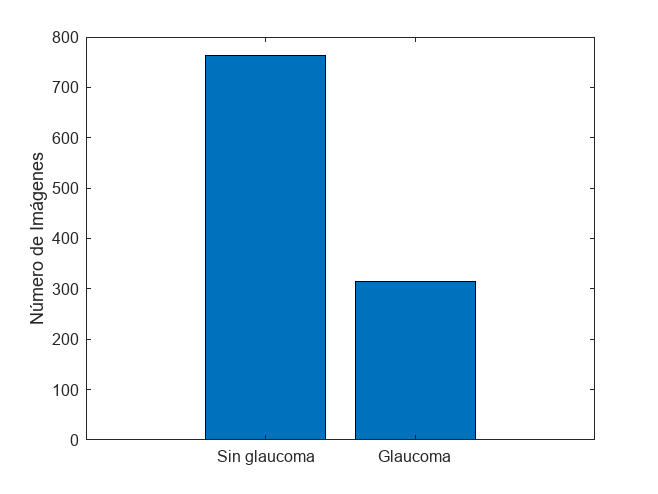

images_with_error_SEGM = T_error.image(T_error.error_segmentacion == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error_SEGM);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

images_with_error_DISCO = T_error.image(T_error.error_disco == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error_DISCO);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

images_with_error_COPA = T_error.image(T_error.error_copa == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error_COPA);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

images_with_error_DISCO2 = T_error.image(T_error.error_disco2 == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error_DISCO2);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

images_with_error_DISCO3 = T_error.image(T_error.error_disco3 == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error_DISCO3);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

images_with_error_NO_DETECTADAS = {'image_1559.jpg','image_1555.jpg','image_1552.jpg','image_1551.jpg','image_1547.jpg','image_1510.jpg','image_1507.jpg','image_1503.jpg','image_1498.jpg','image_1486.jpg','image_1484.jpg','image_1479.jpg','image_1474.jpg','image_1472.jpg','image_1469.jpg','image_1468.jpg','image_1466.jpg','image_1463.jpg','image_1460.jpg','image_1458.jpg','image_1455.jpg','image_1454.jpg','image_1446.jpg','image_1438.jpg','image_1433.jpg','image_1430.jpg','image_1420.jpg','image_1419.jpg','image_1406.jpg','image_1402.jpg','image_1396.jpg','image_1390.jpg','image_1370.jpg','image_1364.jpg','image_1360.jpg','image_1345.jpg','image_1327.jpg','image_1318.jpg','image_1309.jpg','image_1282.jpg','image_1268.jpg','image_1232.jpg','image_1229.jpg','image_1200.jpg','image_1163.jpg','image_1152.jpg','image_1135.jpg','image_1126.jpg','image_1121.jpg','image_1098.jpg','image_1093.jpg','image_1090.jpg','image_1082.jpg','image_1028.jpg','image_1001.jpg','image_0995.jpg','image_0992.jpg','image_0979.jpg','image_0972.jpg','image_0945.jpg','image_0926.jpg','image_0925.jpg','image_0922.jpg','image_0918.jpg','image_0905.jpg','image_0902.jpg','image_0901.jpg','image_0886.jpg','image_0869.jpg','image_0831.jpg','image_0830.jpg','image_0827.jpg','image_0791.jpg','image_0781.jpg','image_0778.jpg','image_0766.jpg','image_0759.jpg','image_0728.jpg','image_0715.jpg','image_0695.jpg','image_0691.jpg','image_0664.jpg','image_0649.jpg','image_0645.jpg','image_0630.jpg','image_0617.jpg','image_0612.jpg','image_0609.jpg','image_0586.jpg','image_0580.jpg','image_0574.jpg','image_0572.jpg','image_0562.jpg','image_0549.jpg','image_0537.jpg','image_0532.jpg','image_0514.jpg','image_0513.jpg','image_0464.jpg','image_0441.jpg','image_0436.jpg','image_0426.jpg','image_0417.jpg','image_0389.jpg','image_0387.jpg','image_0373.jpg','image_0354.jpg','image_0340.jpg','image_0333.jpg','image_0301.jpg','image_0291.jpg','image_0269.jpg','image_0265.jpg','image_0221.jpg','image_0214.jpg','image_0203.jpg','image_0187.jpg','image_0181.jpg','image_0178.jpg','image_0177.jpg','image_0165.jpg','image_0157.jpg','image_0137.jpg','image_0135.jpg','image_0127.jpg','image_0042.jpg','image_0028.jpg',};
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error_NO_DETECTADAS);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

num_buenas = sum(T.glaucoma==0);
num_malas = sum(T.glaucoma==1);

% Crear un vector con el número de imágenes para cada categoría
num_imagenes = [num_buenas, num_malas];

% Crear un gráfico de barras
figure;
bar(num_imagenes);
ylabel('Número de Imágenes');
xticklabels({'Sin glaucoma', 'Glaucoma'});

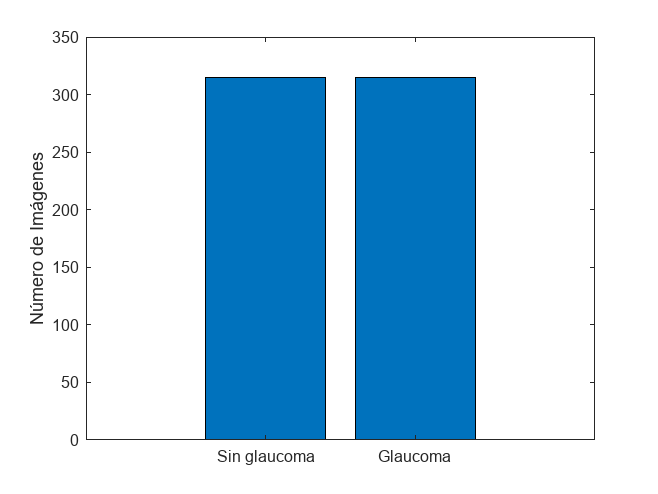


indices_buenas = find(T.glaucoma == 0);
indices_malas = find(T.glaucoma == 1);
rng('default'); % Para reproducibilidad
indices_buenas_seleccionadas = datasample(indices_buenas, num_malas, 'Replace', false);
indices_seleccionados = [indices_buenas_seleccionadas; indices_malas];

% Crear un nuevo conjunto de datos con el mismo número de imágenes en cada clase
T = T(indices_seleccionados, :);
num_buenas = sum(T.glaucoma==0);
num_malas = sum(T.glaucoma==1);

% Crear un vector con el número de imágenes para cada categoría
num_imagenes = [num_buenas, num_malas];

% Crear un gráfico de barras
figure;
bar(num_imagenes);
ylabel('Número de Imágenes');
xticklabels({'Sin glaucoma', 'Glaucoma'});

### ANALISIS

#### Caracteristicas de color

variables=T.Properties.VariableNames

variables = 1×91 cell array
    {'entropiaRGB'}    {'entropiaHSV'}    {'entropiaGris'}    {'entropiaR'}    {'entropiaG'}    {'entropiaB'}    {'entropiaNRR'}    {'entropiaNRR_HSV'}    {'rango_dinamicoRGB'}    {'rango_dinamicoHSV'}    {'rango_dinamicoGris'}    {'rango_dinamicoR'}    {'rango_dinamicoG'}    {'rango_dinamicoB'}    {'rango_dinamicoNRR'}    {'rango_dinamicoNRR_HSV'}    {'std_intensidadRGB'}    {'std_intensidadHSV'}    {'std_intensidadGris'}    {'std_intensidadR'}    {'std_intensidadG'}    {'std_intensidadB'}    {'std_intensidadNRR'}    {'std_intensidadNRR_HSV'}    {'varianzaRGB'}    {'varianzaHSV'}    {'varianzaGris'}    {'varianzaR'}    {'varianzaG'}    {'varianzaB'}    {'varianzaNRR'}    {'varianzaNRR_HSV'}    {'mediaRGB'}    {'mediaHSV'}    {'mediaGris'}    {'mediaR'}    {'mediaG'}    {'mediaB'}    {'mediaNRR'}    {'mediaNRR_HSV'}    {'energiaRGB'}    {'energiaHSV'}    {'energiaGris'}    {'energiaR'}    {'energiaG'}    {'energiaB'}    {'energiaNRR'}    {'energiaNRR_HSV'}  

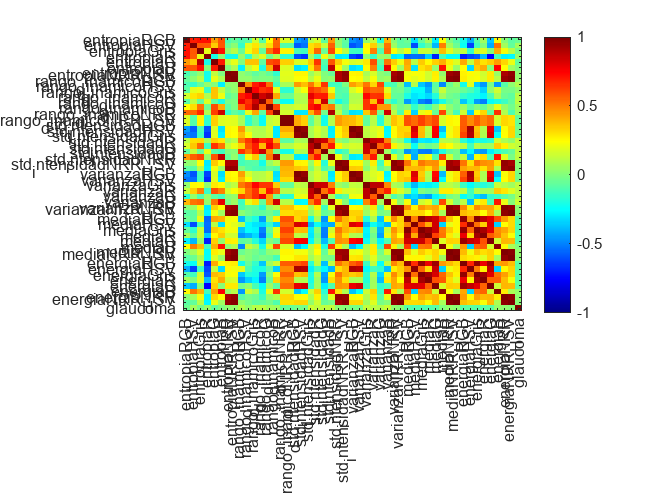

selected_variables = variables(1:48);
selected_variables = [selected_variables, 'glaucoma'];

% Selecciona los datos correspondientes
X = T{:, selected_variables};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:100);
xticklabels(selected_variables(:));
yticks(1:100);
yticklabels(selected_variables(:));
colormap(jet); colorbar;

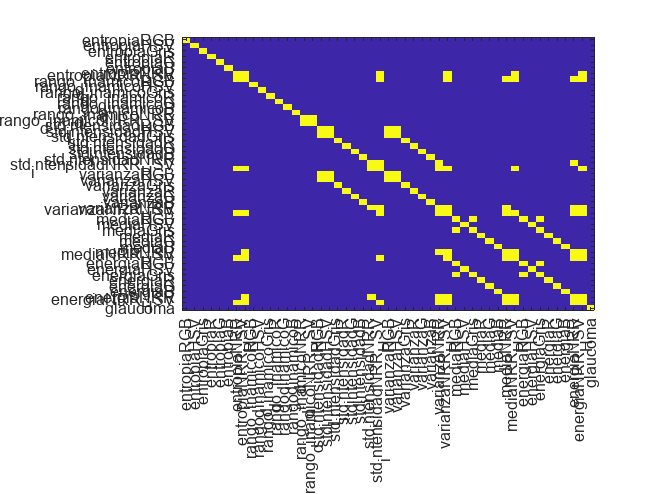


figure;
imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:100);
xticklabels(selected_variables(:));
yticks(1:100);
yticklabels(selected_variables(:));

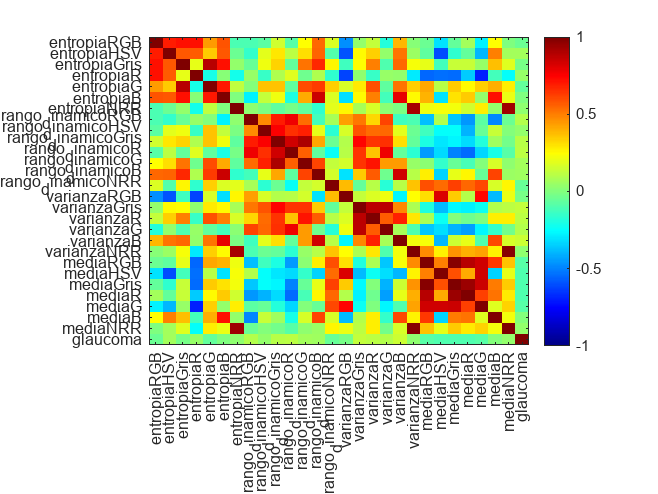


% Las segmentadas de RGB y de HSV estan muy correalcionadas -> eliminar
T.entropiaNRR_HSV=[];
T.rango_dinamicoNRR_HSV=[];
T.varianzaNRR_HSV=[];
T.std_intensidadNRR_HSV=[];
T.mediaNRR_HSV=[];
T.energiaNRR_HSV=[];

% Las varianzas y los rangos dinamicos estan muy correlacionados
T.std_intensidadRGB=[];
T.std_intensidadHSV=[];
T.std_intensidadGris=[];
T.std_intensidadR=[];
T.std_intensidadG=[];
T.std_intensidadB=[];
T.std_intensidadNRR=[];

% Varianza RGB y HSV
T.varianzaHSV = [];

% Media y energia 
T.energiaRGB=[];
T.energiaHSV=[];
T.energiaGris=[];
T.energiaR=[];
T.energiaG=[];
T.energiaB=[];
T.energiaNRR=[];

variables=T.Properties.VariableNames;
selected_variables = variables(1:27);
selected_variables = [selected_variables, 'glaucoma'];

% Selecciona los datos correspondientes
X = T{:, selected_variables};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:100);
xticklabels(selected_variables(:));
yticks(1:100);
yticklabels(selected_variables(:));
colormap(jet); colorbar;

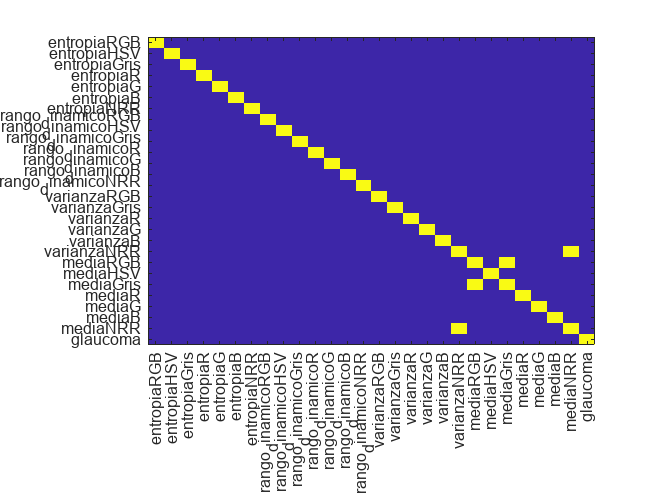


figure;
imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:100);
xticklabels(selected_variables(:));
yticks(1:100);
yticklabels(selected_variables(:));

#### Caracteristicas de textura

variables=T.Properties.VariableNames

variables = 1×70 cell array
    {'entropiaRGB'}    {'entropiaHSV'}    {'entropiaGris'}    {'entropiaR'}    {'entropiaG'}    {'entropiaB'}    {'entropiaNRR'}    {'rango_dinamicoRGB'}    {'rango_dinamicoHSV'}    {'rango_dinamicoGris'}    {'rango_dinamicoR'}    {'rango_dinamicoG'}    {'rango_dinamicoB'}    {'rango_dinamicoNRR'}    {'varianzaRGB'}    {'varianzaGris'}    {'varianzaR'}    {'varianzaG'}    {'varianzaB'}    {'varianzaNRR'}    {'mediaRGB'}    {'mediaHSV'}    {'mediaGris'}    {'mediaR'}    {'mediaG'}    {'mediaB'}    {'mediaNRR'}    {'contrast_red'}    {'homogeneity_red'}    {'correlation_red'}    {'contrast_green'}    {'homogeneity_green'}    {'correlation_green'}    {'contrast_blue'}    {'homogeneity_blue'}    {'correlation_blue'}    {'contrast_gray'}    {'homogeneity_gray'}    {'correlation_gray'}    {'contrast_NRR'}    {'homogeneity_NRR'}    {'correlation_NRR'}    {'CDR'}    {'DDLS'}    {'NRR'}    {'dist1'}    {'dist2'}    {'dist3'}    {'dist4'}    {'radioD'}    {'radioC'}  

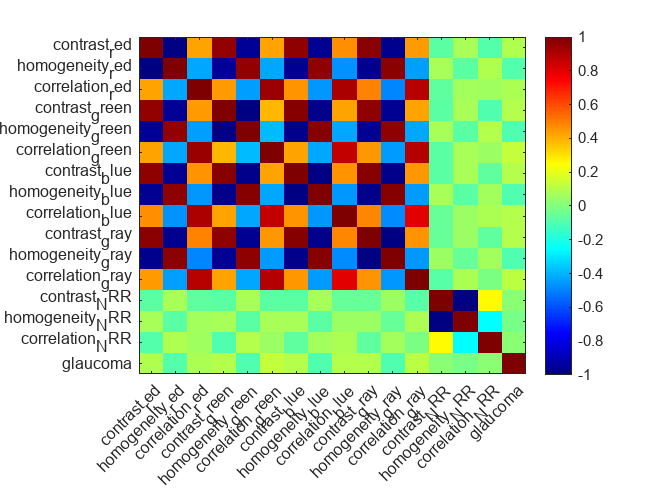

selected_variables = variables(28:42);
selected_variables = [selected_variables, 'glaucoma'];

% Selecciona los datos correspondientes
X = T{:, selected_variables};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:100);
xticklabels(selected_variables(:));
yticks(1:100);
yticklabels(selected_variables(:));
colormap(jet); colorbar;

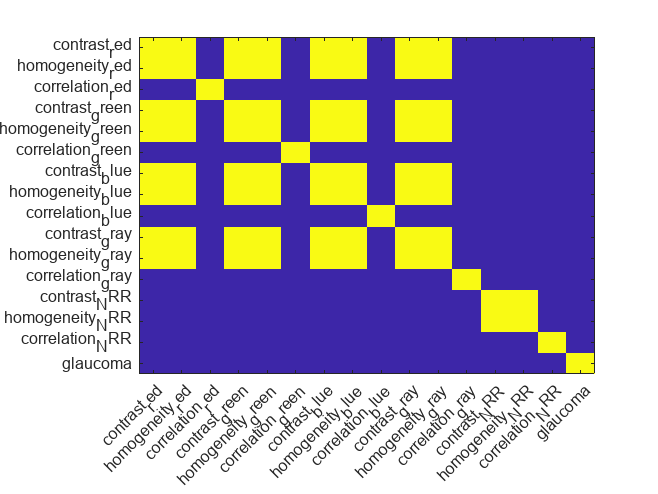


figure;
imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:100);
xticklabels(selected_variables(:));
yticks(1:100);
yticklabels(selected_variables(:));

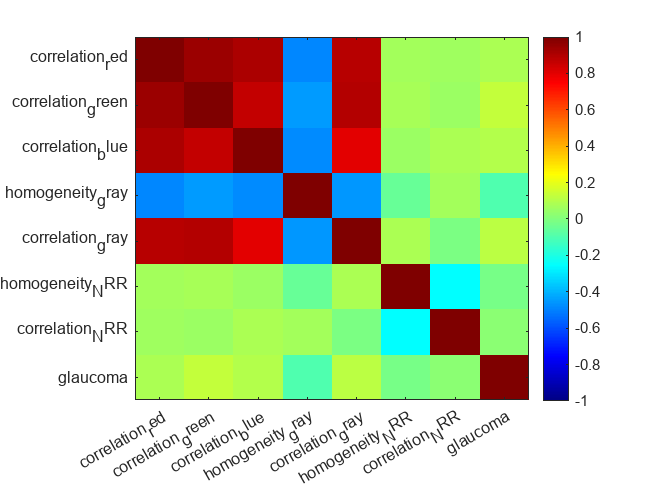


% Homogenidad y contraste muy correlacionadas 
T.contrast_red = [];
T.contrast_green = [];
T.contrast_blue = [];
T.contrast_gray = [];
T.contrast_NRR = [];
% Homogenidad muy correlacionado entre ellas
T.homogeneity_red = [];
T.homogeneity_green = [];
T.homogeneity_blue = [];

variables=T.Properties.VariableNames;
selected_variables = variables(28:34);
selected_variables = [selected_variables, 'glaucoma'];

% Selecciona los datos correspondientes
X = T{:, selected_variables};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:100);
xticklabels(selected_variables(:));
yticks(1:100);
yticklabels(selected_variables(:));
colormap(jet); colorbar;

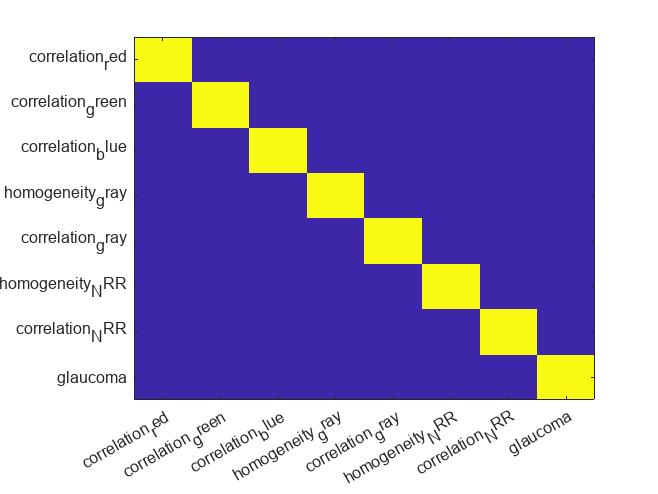


figure;
imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:100);
xticklabels(selected_variables(:));
yticks(1:100);
yticklabels(selected_variables(:));

#### Caracteristicas de disco-copa

variables=T.Properties.VariableNames

variables = 1×62 cell array
    {'entropiaRGB'}    {'entropiaHSV'}    {'entropiaGris'}    {'entropiaR'}    {'entropiaG'}    {'entropiaB'}    {'entropiaNRR'}    {'rango_dinamicoRGB'}    {'rango_dinamicoHSV'}    {'rango_dinamicoGris'}    {'rango_dinamicoR'}    {'rango_dinamicoG'}    {'rango_dinamicoB'}    {'rango_dinamicoNRR'}    {'varianzaRGB'}    {'varianzaGris'}    {'varianzaR'}    {'varianzaG'}    {'varianzaB'}    {'varianzaNRR'}    {'mediaRGB'}    {'mediaHSV'}    {'mediaGris'}    {'mediaR'}    {'mediaG'}    {'mediaB'}    {'mediaNRR'}    {'correlation_red'}    {'correlation_green'}    {'correlation_blue'}    {'homogeneity_gray'}    {'correlation_gray'}    {'homogeneity_NRR'}    {'correlation_NRR'}    {'CDR'}    {'DDLS'}    {'NRR'}    {'dist1'}    {'dist2'}    {'dist3'}    {'dist4'}    {'radioD'}    {'radioC'}    {'centro1'}    {'centro2'}    {'energy_db3'}    {'average_dh_db3'}    {'average_dv_db3'}    {'energy_sym3'}    {'average_dh_sym3'}    {'average_dv_sym3'}    {'energy_bior33'}

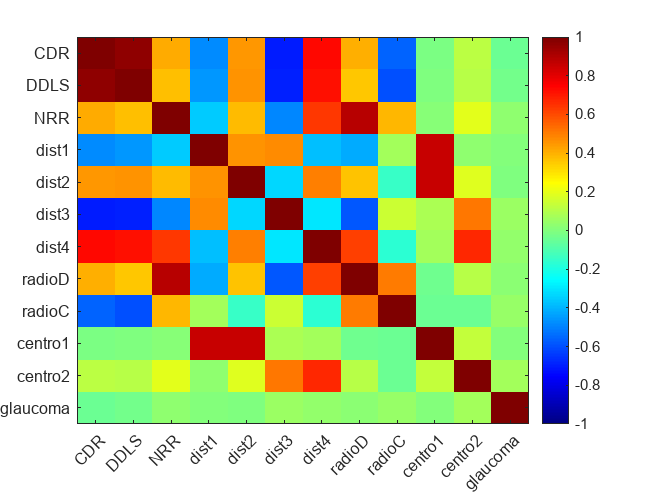

selected_variables = variables(35:45);
selected_variables = [selected_variables, 'glaucoma'];

% Selecciona los datos correspondientes
X = T{:, selected_variables};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:100);
xticklabels(selected_variables(:));
yticks(1:100);
yticklabels(selected_variables(:));
colormap(jet); colorbar;

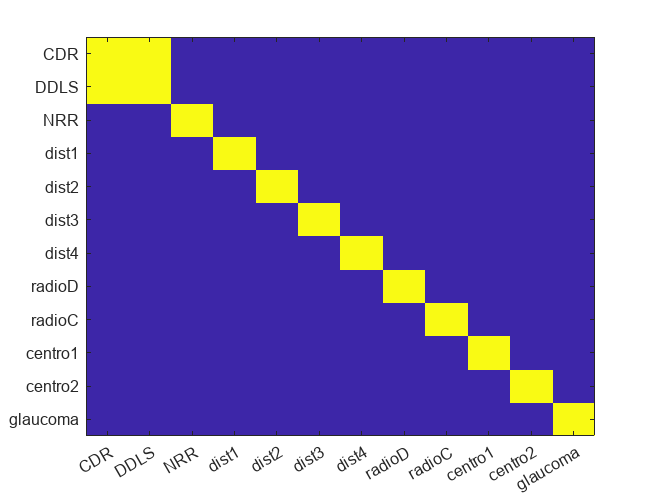


figure;
imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:100);
xticklabels(selected_variables(:));
yticks(1:100);
yticklabels(selected_variables(:));


T.dist1=[];
T.dist2=[];
T.dist3=[];
T.dist4=[];
T.centro1=[];
T.centro2=[];
T.radioD = [];
T.radioC = [];
T.DDLS = [];


Correlacion general

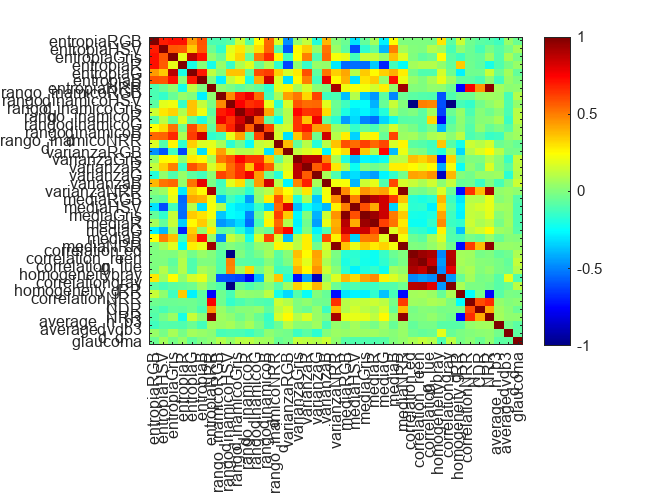

% T.average_dh_db3 = [];
% T.average_dv_db3 = [];
T.average_dh_sym3 = [];
T.average_dv_sym3= [];
T.average_dh_bior33 = [];
T.average_dv_bior33 = [];
T.average_dh_bior35 = [];
T.average_dv_bior35= [];
T.average_dh_bior37 = [];
T.average_dv_bior37= [];
T.energy_db3 = [];
T.energy_sym3 = [];
T.energy_bior33 = [];
T.energy_bior35 = [];
T.energy_bior37 = [];

T.imagen=[];
variables=T.Properties.VariableNames;

X = T{:, :};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:100);
xticklabels(variables(:));
yticks(1:100);
yticklabels(variables(:));
colormap(jet); colorbar;

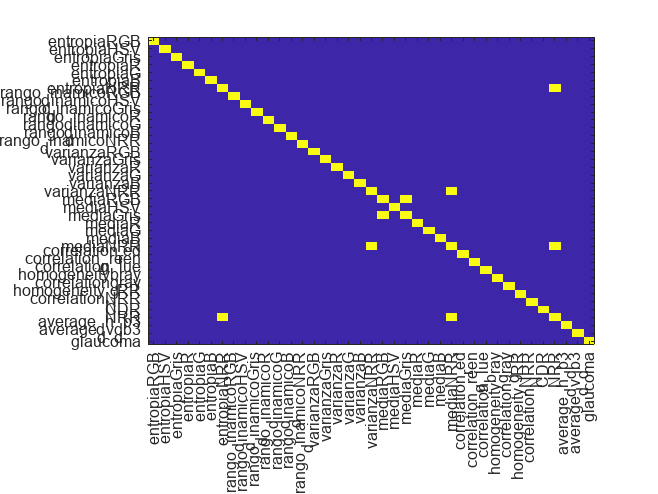


figure;
imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:100);
xticklabels(variables(:));
yticks(1:100);
yticklabels(variables(:));

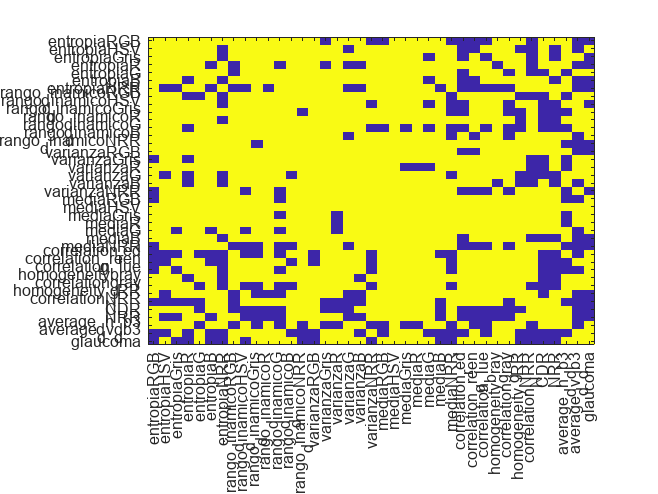


figure;
imagesc(abs(R)>0.05); clim([0 1]);
xticks(1:100);
xticklabels(variables(:));
yticks(1:100);
yticklabels(variables(:));


T.entropiaRGB = [];
T.entropiaGris = [];
T.entropiaB = [];
T.rango_dinamicoHSV = [];
T.mediaB=[];
T.mediaNRR=[];
T.homogeneity_NRR = [];
T.correlation_NRR = [];
T.NRR=[];

#### Preprocessing

[n, ~]=size(T);

T.glaucoma = cellstr(num2str(T.glaucoma)); %convertir quality en variable categorica
for i = 1:n
    if T.glaucoma{i} == '1'
        T.glaucoma{i} = 'Glaucoma';
    elseif T.glaucoma{i} == '0'
        T.glaucoma{i} = 'No Glaucoma';
    end
end

### 2. Data split

rng(6); 
p = 0.2;
cv_out = cvpartition(T.glaucoma, 'HoldOut', p, 'Stratify', true); 
% 20% -> pruebas
% 80% -> entrenar el modelo. 
% 'Stratify', true asegura que la distribución de clases se mantenga tanto en los conjuntos de entrenamiento como en los de prueba

T_train = T(cv_out.training, :); 
T_test  = T(cv_out.test, :);

k = 10; % técnica de validación cruzada de 10 pliegues
cv_in = cvpartition(T_train.glaucoma, 'KFold', k, 'Stratify', true);

%PONER Z-SCORE

### **3. Model training**

results = table;

#### **K-nearest neighbors (KNN)**

**con todas el mejor knn (neighbords 3)**

mdl_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 3, 'CVPartition', cv_in); % number of neighbors: 3
mdl_loss = kfoldLoss(mdl_knn); % mean error value

Y_pred = kfoldPredict(mdl_knn);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("knn", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Classification Trees**

mdl_tree = fitctree(T_train, 'glaucoma', 'CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_tree);

Y_pred = kfoldPredict(mdl_tree);

accuracy = sum(strcmp(T_train.glaucoma, Y_pred)) / height(T_train);
results = [results; table("tree", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

first_fold_tree = mdl_tree.Trained{1};
view(first_fold_tree, 'Mode', 'graph');

#### Naive Bayes

mdl_NB = fitcnb(T_train, 'glaucoma','CVPartition', cv_in);
% mdl_loss = kfoldLoss(mdl_NB);

Y_pred = kfoldPredict(mdl_NB);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("naive_bayes", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### Discriminant Analysis

- **LDA**: asume que las matrices de covarianza de cada clase son iguales.

mdl_lda = fitcdiscr(T_train, 'glaucoma','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_lda);
Y_pred = kfoldPredict(mdl_lda);
accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);

results = [results; table("LDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

- **QDA:** asume que las matrices de covarianza de cada clase son diferentes.

% mdl_qda = fitcdiscr(T_train, 'glaucoma','DiscrimType','quadratic','CVPartition',cv_in);
% mdl_loss = kfoldLoss(mdl_qda);
% 
% Y_pred = kfoldPredict(mdl_qda);
% 
% accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
% results = [results; table("QDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Support Vector Machines (SVM)**

mdl_svm = fitcecoc(T_train, 'glaucoma','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);

Y_pred = kfoldPredict(mdl_svm);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("SVM", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

### 4. Model comparison

results

results = 5×3 table
        model         loss      accuracy
    _____________    _______    ________

    "knn"            0.50777    0.47619 
    "tree"           0.48214    0.51786 
    "naive_bayes"    0.48214    0.57143 
    "LDA"            0.51813    0.47222 
    "SVM"             0.5119     0.4881 


[~, best_model] = max(results.accuracy);
results(best_model, :) %balance accuracy

ans = 1×3 table
        model         loss      accuracy
    _____________    _______    ________

    "naive_bayes"    0.48214    0.57143 


### 5. Final model testing

mdl_final_SVM = fitcecoc(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_SVM, T_test);

loss_final2 = loss(mdl_final_SVM, T_test)

loss_final2 = 0.5397

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final2 = 0.4603

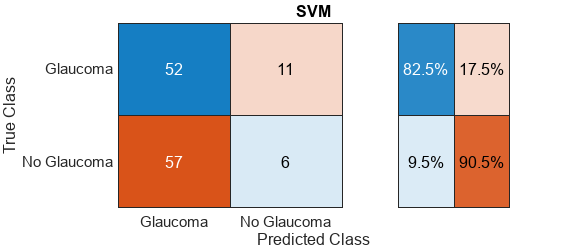


Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('SVM');


mdl_final_LDA = fitcdiscr(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_LDA, T_test);

loss_final2 = loss(mdl_final_LDA, T_test)

loss_final2 = 0.4921

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final2 = 0.5079

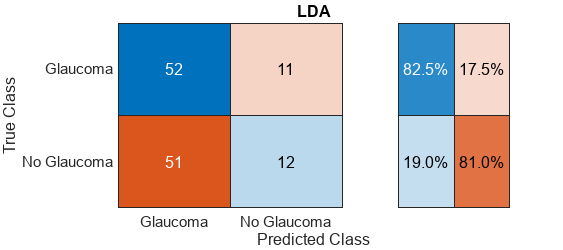


Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('LDA');

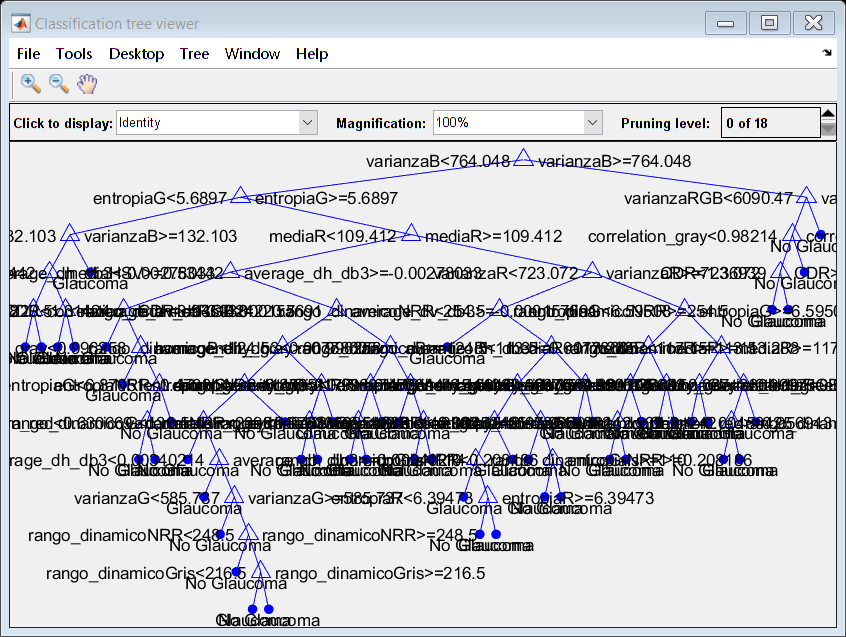


mdl_final_tree = fitctree(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_tree, T_test);
% 
% first_fold_tree = mdl_final_tree.view{1};
view(mdl_final_tree, 'Mode', 'graph');


loss_final2 = loss(mdl_final_tree, T_test)

loss_final2 = 0.4921

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final2 = 0.5079

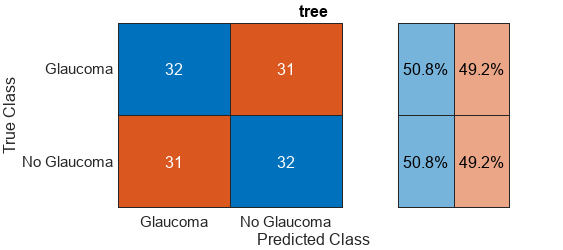


Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('tree');


mdl_final_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 6);
Y_pred2 = predict(mdl_final_knn, T_test);

loss_final2 = loss(mdl_final_knn, T_test)

loss_final2 = 0.5476

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final2 = 0.4524

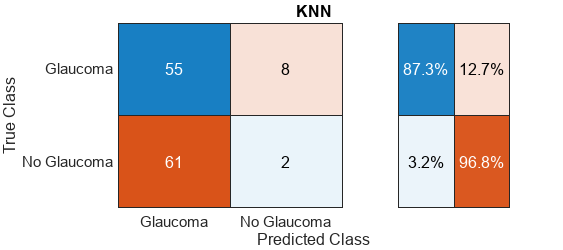


Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('KNN');


mdl_final_nb = fitcnb(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_nb, T_test);

loss_final2 = loss(mdl_final_nb, T_test)

loss_final2 = 0.3968

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final2 = 0.6032

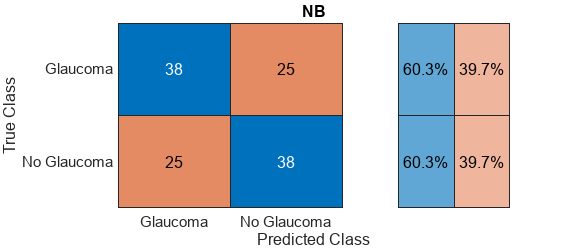


Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('NB');


% mdl_final_QDA = fitcdiscr(T_train, 'glaucoma','DiscrimType','quadratic');
% Y_pred2 = predict(mdl_final_QDA, T_test);
% 
% loss_final2 = loss(mdl_final_QDA, T_test)
% accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma);
% 
% Y_test  = T.glaucoma(cv_out.test);
% 
% figure('Position', [0 0 450 200]);
% confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('QDA');

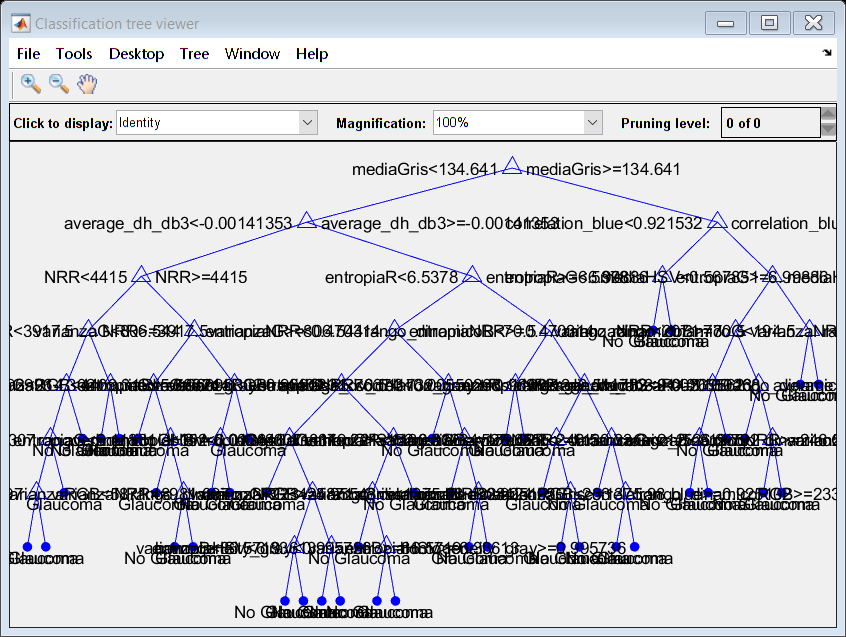

mdl_final_RF = TreeBagger(50, T_train, 'glaucoma', 'Method', 'classification');
Y_pred_RF = predict(mdl_final_RF, T_test);
% Pérdida (error) del modelo
% loss_RF = loss(mdl_final_RF, T_test);
first_fold_tree = mdl_final_RF.Trees{1};
view(first_fold_tree, 'Mode', 'graph');

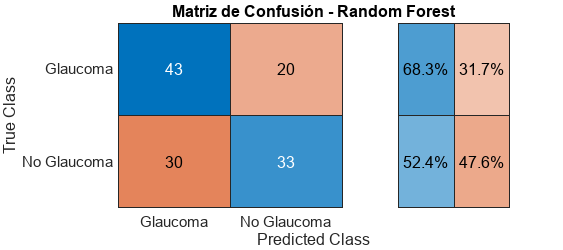


% Exactitud (accuracy) del modelo
accuracy_RF = sum(strcmp(Y_pred_RF, T_test.glaucoma)) / height(T_test.glaucoma);
figure('Position', [0 0 450 200]);
confusionchart(T_test.glaucoma, Y_pred_RF, 'RowSummary', 'row-normalized'); 
title('Matriz de Confusión - Random Forest');

% T = readtable("CaracteristicasDETECCION2.csv");
% 
% % Realiza las predicciones
% prediccion4 = predict(mdl_final_LDA, T);
% 
% % Convierte las predicciones a 0 y 1
% prediccion_numerica = strcmp(prediccion4, 'Glaucoma');
% 
% % Compara las predicciones numéricas con los valores reales de glaucoma en T
% es_correcto = (prediccion_numerica == T.glaucoma);
% 
% % Crea una nueva tabla que incluya las columnas imagen, glaucoma, prediccion y si la predicción fue correcta o no
% GLAUCOMA_PRED = table(T.imagen, T.glaucoma, prediccion4, es_correcto, 'VariableNames', {'imagen', 'glaucoma', 'prediccion', 'es_correcto'})
% num_correctas = sum(es_correcto)